#### Clear environment

clear
close all
clc

# Non linear equations

# Part 1 - Growth Model


$$p(t) = \frac{p_m}{1 + (\frac{p_m}{p_0} - 1) e^{-Kp_mt}}$$


given $K = 2*10^-6$ and $p_0 = p(0) = 100$

after plotting $t_1 = 60$ we have $p_1 = p(t_1) = 25000$

solving for $p_m$:


$$(1 + (\frac{p_m}{p_0} - 1) e^{-Kp_mt})p_1 = p_m$$



$$(1 + (\frac{p_m}{p_0} - 1) e^{-Kp_mt})p_1 - p_m = 0$$



$$f_{p_m} = p_1(1 + (\frac{p_m}{p_0} - 1) e^{-Kp_mt}) - p_m$$


with derivative:


$$f'_{p_m} = -1 + \frac{p_1 e^{-K p_mt}(1 + K(-p_m + p_0)t)}{p_0}$$


The function as a code are defined at the end of the script.

## Functions definition

% interval to plot
a = 0; b = 100000;

% functions parameters:
K = 2e-6; p0 = 100; t1 = 60; p1 = 25000;

% function for p_m:
fun = @(pm) logistic_growth_pm(pm, K, p0, t1, p1);
fun_prime = @(pm) logistic_growth_pm_prime(pm, K, p0, t1, p1);

% termination criteria
tolerance=1e-14;
kmax=1e3;

## plot function

f = figure();
f.Name = 'Functions';
f.NumberTitle = 'off';
f.Position = [0, 1000, 800, 600];

subplot(2, 2, 1);
fplot(fun, [a, b]);

grid on;

title('$f: p_m \to f(p_m) = linear\ equation\ of\ p_m$', 'interpreter','latex');
subtitle(['as p(', num2str(t1), ') = ', num2str(p1)], 'interpreter','latex');
xlabel("p_m"); ylabel("f(p_m)");
xline(0, ':k'); yline(0, ':k');

subplot(2, 2, 3);
fplot(fun_prime, [a, b]);

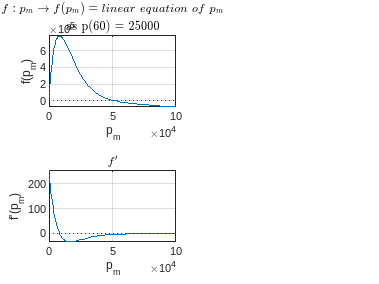

grid on;
title("$f'$", 'interpreter','latex');
xlabel("p_m"); ylabel("f'(p_m)");
xline(0, ':k'); yline(0, ':k');

## Approximate $p_m$ 

### Newton method

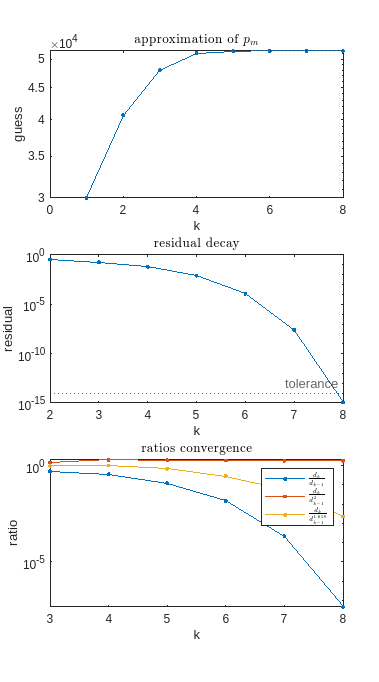

x0 = 30000;
pm = newton( ...
    fun, fun_prime, x0, kmax, tolerance ...
);

### Fixed Secant method

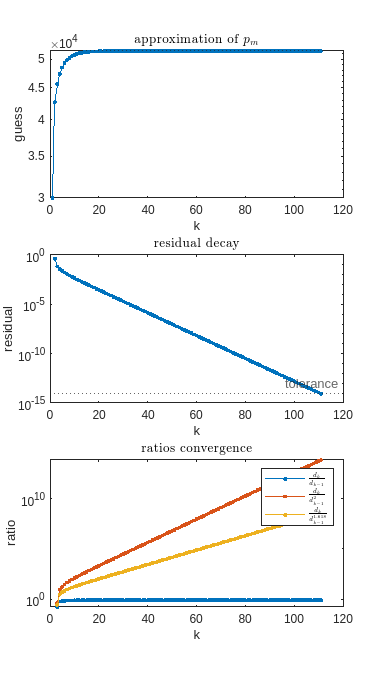

x1 = 35000;
pm_fx_secant = fxsecant( ...
    fun, x0, x1, kmax, tolerance ...
);

### Secant method

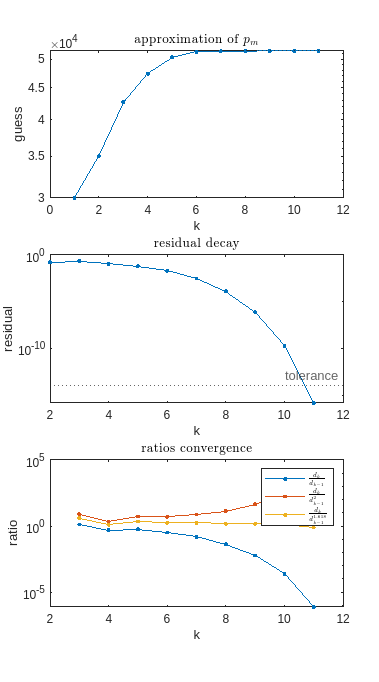

pm_secant = secant( ...
    fun, x0, x1, kmax, tolerance ...
);

#### Check for convergence of the three methods into a single solution


convergence_tolerance = 1e-8;
if abs(pm - pm_fx_secant) > convergence_tolerance || ...
    abs(pm - pm_secant) > convergence_tolerance
    error("the three methods doesn't converge");
end

The final solution is printed out

disp(['final approximation of p_m: ', num2str(pm)]);

## Define logistic growth model

% interval to plot
a = 0; b = 250;

% function definition
p_fun = @(t) logistic_growth(t, pm, p0, K);

figure(f);
subplot(2, 2, 2);
fplot(p_fun, [a, b]);

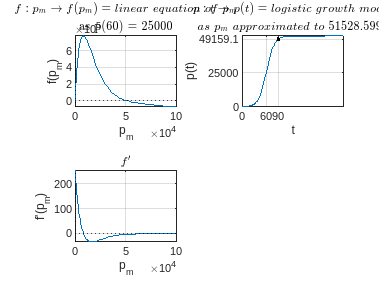

grid on;
title('$p: t \to p(t) = logistic\ growth\ model$', 'interpreter', 'latex');
subtitle(['$as\ p_m\ approximated\ to\ ', num2str(pm), '$'], 'interpreter', 'latex');
xlabel("t"); ylabel("p(t)");
hold on;

T = 90;
res = p_fun(T);
yticks([0, p1, res, pm]); yticklabels([0, p1, res, pm]);
xticks([0, t1, T]); xticklabels([0, t1, T]);
plot(T, res, 'k.');
hold off;


disp(['p(', num2str(T), ') = ', num2str(res)]);

p(90) = 49159.0667


## Picard Iteration

eh...

# Part 2 - Non linear systems

TODO

## Appendix

#### Tested functions

function f = logistic_growth(t, pm, p0, K)
    f = pm / (1 + (pm / p0 - 1) * exp(-K * pm * t));
end

function f = logistic_growth_pm(pm, K, p0, t1, p1)
    f = p1 * (1 + (pm / p0 - 1) * exp(-K * pm * t1)) - pm;
end

function f = logistic_growth_pm_prime(pm, K, p0, t1, p1)
    f = (exp(-K * pm * t1) * (K * p1 * t1 * (p0 - pm) + p0 * (-exp(K * pm * t1)) + p1)) / p0;
end